clearvars -except data results v_results all_fiji_data

## Analysis of segmented data

### Description of data obtained from computer vision code

The computer vision code detects cells present in a timepoint from the images obtained through epi-flourescent microscopy, returning a table of properties for every detected cell in a side channel, such as it's x,y coordinates; timepoint; area; and pixel intensities. The list of properties generated are displayed below, and a table of values from a side channel. Each row represents the detection of a cell.

The description of these properties can be found here: [https://imagej.nih.gov/ij/docs/menus/analyze.html](https://imagej.nih.gov/ij/docs/menus/analyze.html)

load names.mat
example_data_names = horzcat("RFP_"+names,"YFP_"+names(22),"YFP_"+names(27))

example_data_names = 1×37 string array
    "RFP_N"    "RFP_Area"    "RFP_Mean"    "RFP_StdDev"    "RFP_Mode"    "RFP_Min"    "RFP_Max"    "RFP_X"    "RFP_Y"    "RFP_XM"    "RFP_YM"    "RFP_Perim."    "RFP_BX"    "RFP_BY"    "RFP_Width"    "RFP_Height"    "RFP_Major"    "RFP_Minor"    "RFP_Angle"    "RFP_Circ."    "RFP_Feret"    "RFP_IntDen"    "RFP_Median"    "RFP_Skew"    "RFP_Kurt"    "RFP_%Area"    "RFP_RawIntDen"    "RFP_Slice"    "RFP_FeretX"    "RFP_FeretY"    "RFP_FeretAngle"    "RFP_MinFeret"    "RFP_AR"    "RFP_Round"    "RFP_Solidity"    "YFP_IntDen"    "YFP_RawIntDen"


example_fiji = array2table(all_fiji_data{1,1},"VariableNames",example_data_names)

example_fiji = 13050×37 table
    RFP_N    RFP_Area    RFP_Mean    RFP_StdDev    RFP_Mode    RFP_Min    RFP_Max    RFP_X     RFP_Y     RFP_XM    RFP_YM    RFP_Perim.    RFP_BX    RFP_BY    RFP_Width    RFP_Height    RFP_Major    RFP_Minor    RFP_Angle    RFP_Circ.    RFP_Feret    RFP_IntDen    RFP_Median    RFP_Skew    RFP_Kurt    RFP_%Area    RFP_RawIntDen    RFP_Slice    RFP_FeretX    RFP_FeretY    RFP_FeretAngle    RFP_MinFeret    RFP_AR

### Detecting Division Events and cell lifetimes

First, mother cells are detected by sorting the data tables (obtained from the computer vision code described above) by the y coordinates of detected cells and timepoints. The cells depest in the side trench for each timepoint are the mother cells. After seperating the data for mother cells, their division events are detected by analysing the log area of mother cells over time, as displayed in the plot below.

test_cell = log(data(1,:,2));
plot(test_cell)
title("log area of mother cell over timepoints")
ylabel("log area")
xlabel("timepoints")

Looking closer at divisions, it is evident that cell area follows the stereotypcial sawtooth curve for cell division.

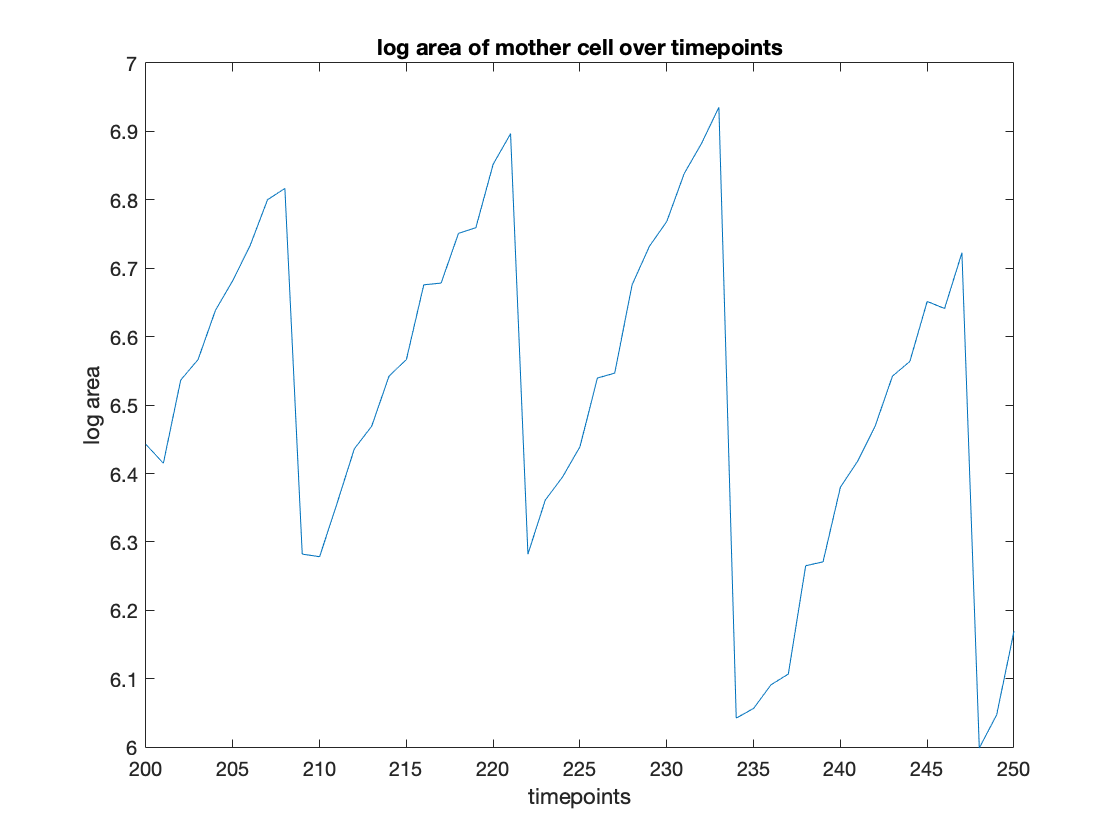

plot(test_cell)
title("log area of mother cell over timepoints")
ylabel("log area")
xlabel("timepoints")
xlim([200 250])

To detect these divison events, the forward difference is taken. Below is the negative of the forward difference of the above log area plot. The peaks are associated with cell division events which can be detected easily using peak finding algorithms.

clf
hold on 
findpeaks(-diff(test_cell),'MinPeakDistance',5,'MinPeakProminence',0.5)
plot([0 721],[0.3,0.3],'r')
hold off

The data for timepoints in between these detected division events are associated with a cell lifetime, defined as a cell that exists between a birth and death event assuming all cells have a unique identity that is not retained after a division event. The growth rate for a lifetime is calculated by finding the linear fit of the log area values for timepoints within the lifetime, and the mean of the median RFP and YFP intensity for those timepoints are also calculated and stored for all mother cell lifetimes in all side channels.

### Identifying errors in division detection

The steps upstream of detecting division events and cell lifetimes are error prone. The computer vision algorithm, altough rather accurate for this experiment (see suplimentary powerpoint) may on occasion miss segment two cells as one or not detect a cell at all. Division events themselves may be abnormal and not comply the thresholding procedures described above. to analysing cell lifetimes, those arrising from errors in these two steps must first be eliminated.

The detected lifetimes are filtered according to the $R^2
$ value between the log area points and the linear fit obtained. Lifetimes with an $R^2
$ value lower than 0.9 are eliminated. Additionally properites of E Coli lifetimes known a priori are also used to eliminate erroneous lifetimes. From previous studies E Coli has been shown to not divide faster than 20 minutes and rarely taking longer than 60 minutes in rich media as used in this experiment. Applying these constraints enables robust detection of cell lifetimes.

The bellow plots indicate the detected lifetimes which will be kept as green points, those which will be discarded in red.

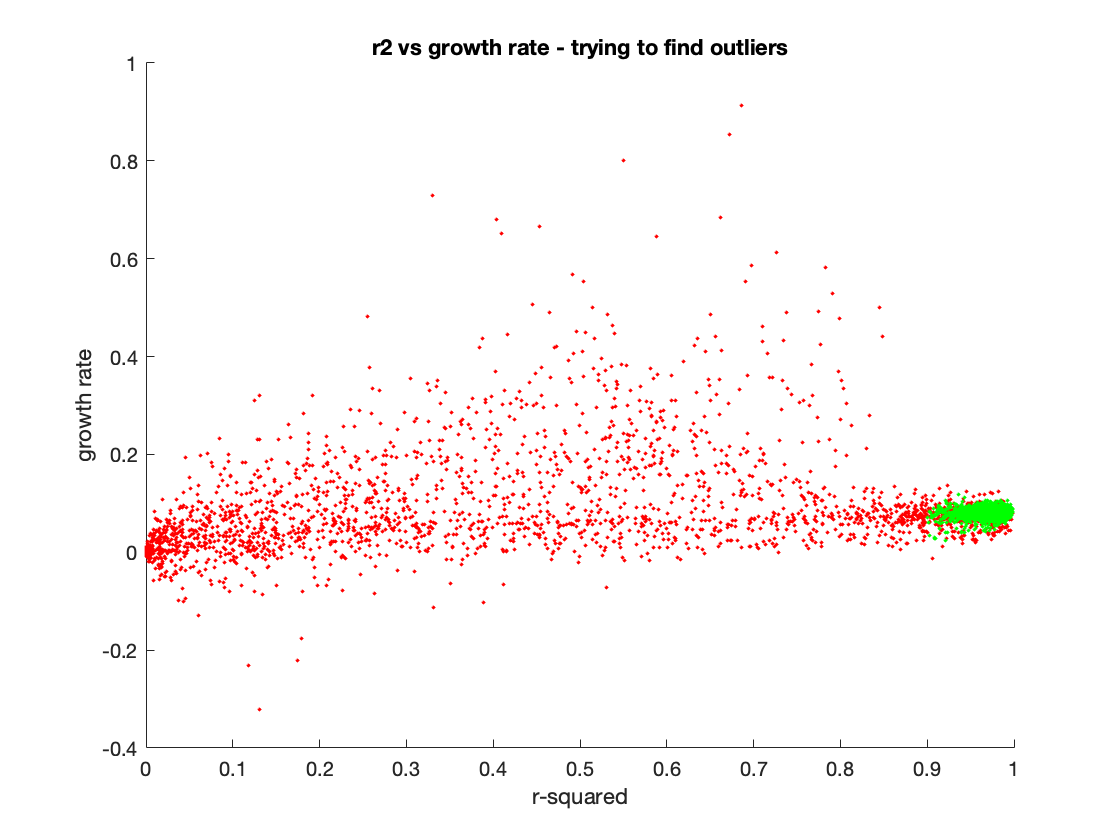

figure
hold on
scatter(v_results.v_r2(~v_results.v_keep),v_results.v_growth_rate(~v_results.v_keep),5,'filled','r')
scatter(v_results.v_r2(v_results.v_keep),v_results.v_growth_rate(v_results.v_keep),5,'filled','g')
xlabel("r-squared")
ylabel("growth rate")
title("r2 vs growth rate - trying to find outliers")
hold off

Most outliers can be removed by limiting $R^2
$ to not include perfect fits, most likely due to a limited number of overvations. Since we are excluding the first and last point observed for a lifetime, up to 4 observations will lead to a perfect fit (2 points needed for linear fit). 

These points are most likely miss segmentations. The sampling rate for this experiment is 2 minutes - so 4 observed points for a cell-lifetime will relate to at most a 12 minute division time - which has never been observed in E Coli, even for strains optimized to have a fast division time(cite). In comparision here we are expressing either flouresent or also β-lactamase - our prior assumption is cell dvision times will not be lower than the fastest divison times of the WT strain in ideal conditions.

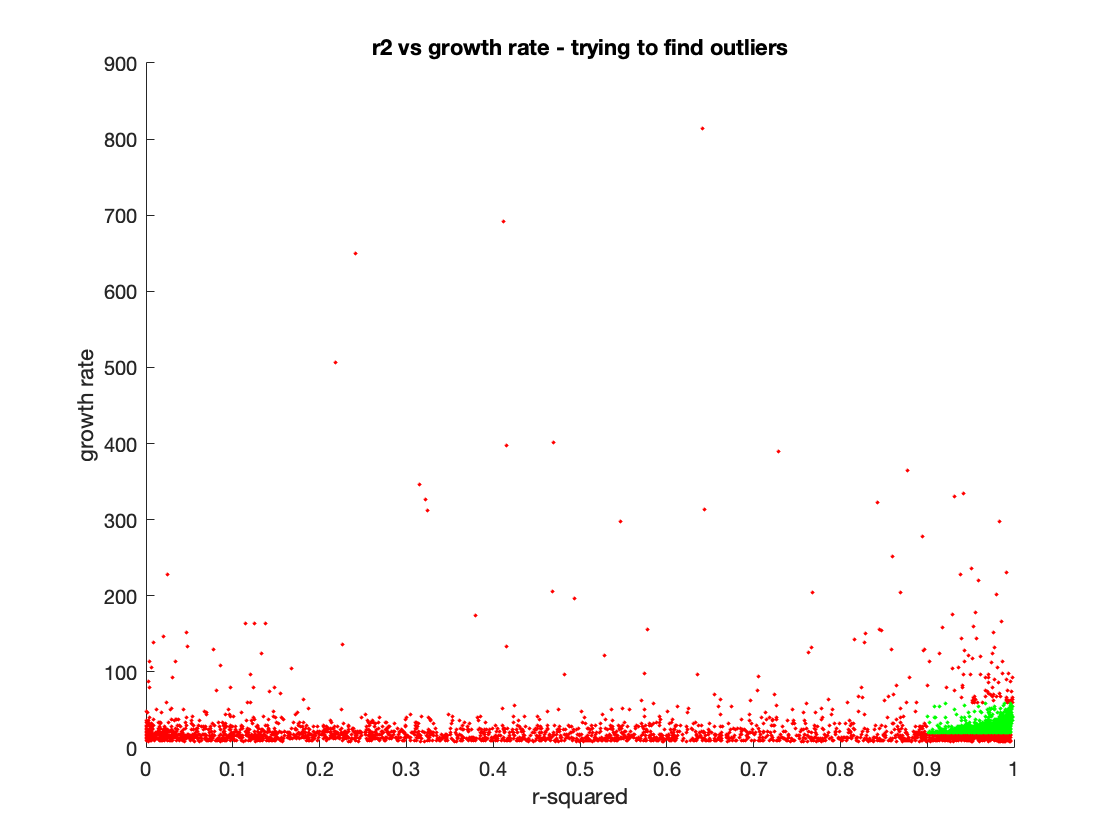

figure
hold on
scatter(v_results.v_r2(~v_results.v_keep),v_results.v_division_time(~v_results.v_keep),5,'filled','r')
scatter(v_results.v_r2(v_results.v_keep),v_results.v_division_time(v_results.v_keep),5,'filled','g')
xlabel("r-squared")
ylabel("growth rate")
title("r2 vs growth rate - trying to find outliers")
hold off

The number of points retained when removing poor $R^2
$ values are:

percent_keeping = sum(v_results.v_keep)/length(v_results.v_keep)

percent_keeping = 0.6171

The effects of removing erroneous lifetime segmentations can be observed by comaring the below plots, one of a trench experiencing regular cell growth and another where the cell has died early in the experiment. Erroneous lifetimes are depicted with the linear fit plotted in red, while those accepted are plotted in green.

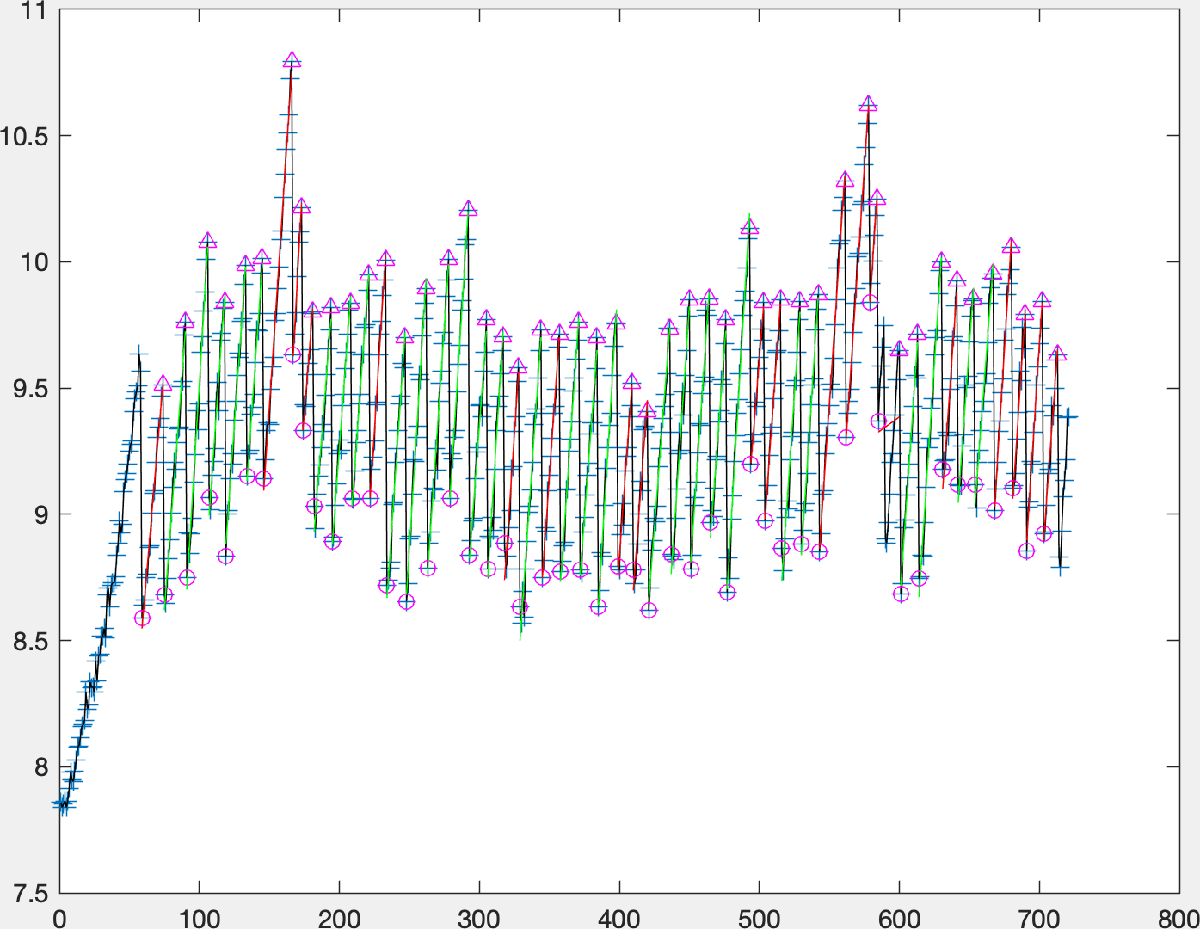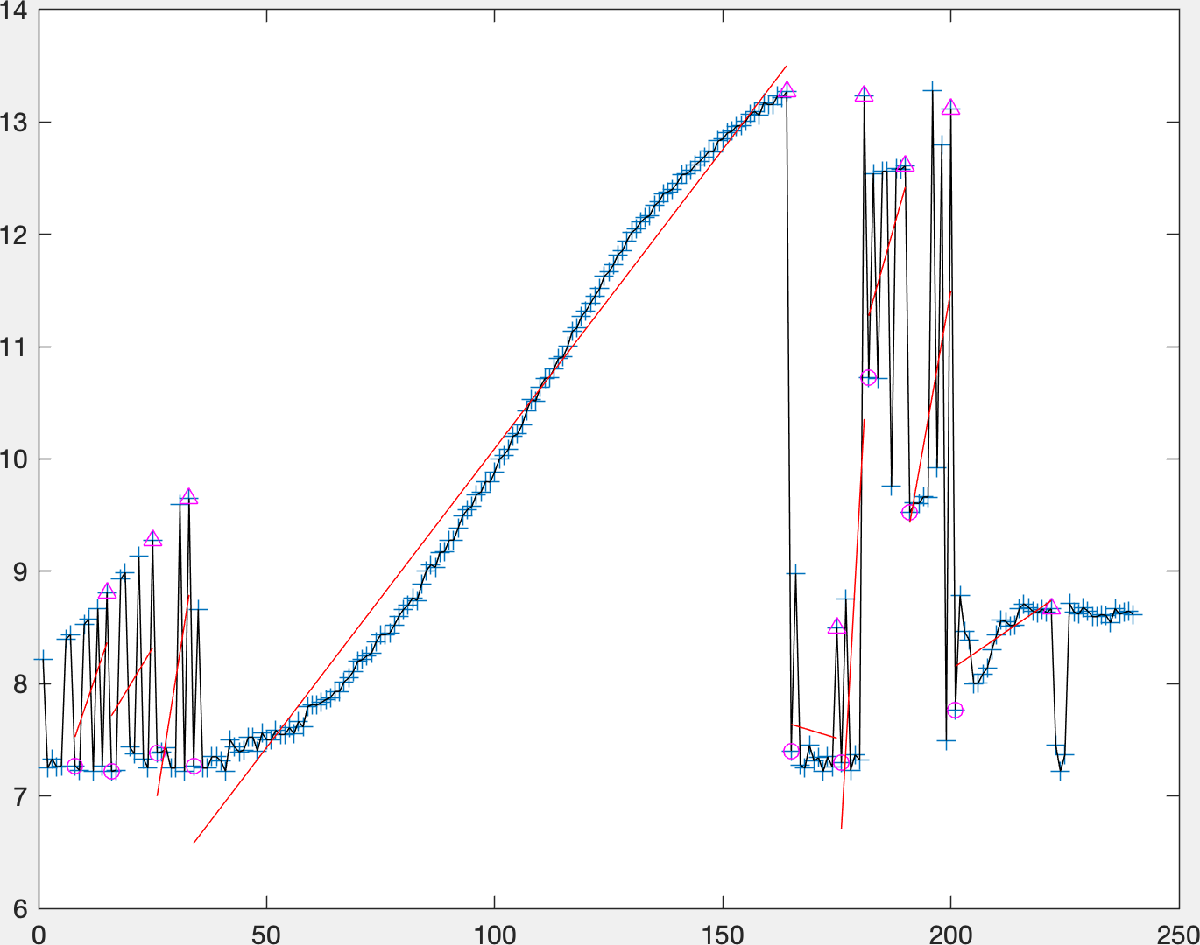

### Finding threshold to seperate populations

Looking at the retained values, we can segment the population in two - those expressing YFP and those that are not.

The cells expressing YFP must contain the plasmid ampR:YFP. The cells not expressing YFP either didn't contain the plasmid initially or lost them. By obeserving the histogram of YFP intentsity we can segment these two populations, a value of 250 seems to be a good threshold as demonstrated in the plot below. The light gray area of the histogram depicts cells classed as not containing the ampR:YFP plasmid, while the dark gray section depicts cells classed as containing the plasmid.

clf

threshold = 250; %threshold to segment populations

%size of graph
ymax = 500;
xmax = 2000;

hold on
patch([threshold,0,0,threshold],[0,0,ymax,ymax],0.9*ones(1,3))
patch([xmax,threshold,threshold,xmax],[0,0,ymax,ymax],0.5*ones(1,3))
histogram(v_results.v_yfp(v_results.v_keep),1000,'FaceColor','yellow')
ylim([0 ymax])
xlim([0 xmax])
xlabel("YFP intensity")
ylabel("frequency")
legend("sensitve population","resisant population","YFP intensity for all cells")
title("using YFP intensity to segment sensitive and resistant populations")
sensitive_id = v_results.v_keep & (v_results.v_yfp<threshold);
resistant_id = v_results.v_keep & (v_results.v_yfp>=threshold);
number_sensitive_lifetimes = sum(sensitive_id);
number_resistant_lifetimes = sum(resistant_id);
hold off

### Population distribution of all observed mother cell lifetimes in experiment

The below bar plot indicates the distribution of lifetimes ascriped to cells containing plasmid (reisistant) and those lacking the plasmid (sensitive) according to the above thresholding proccedure to segment the populations. The growth rate of sensitive cells is expected to be faster due to the lower fitness cost of expressing and replicating the plasmid, hence sensitive cells are expected to divide more frequently that resistant cells and hence exhibit more lifetimes, however there may also be a bias in the initially loaded cells.

bar([number_sensitive_lifetimes,number_resistant_lifetimes]);
%xlabel(["sensitive","resistant"])
set(gca,'xticklabel',["sensitive","resistant"])
ylabel("number of lifetimes observed")
title("number of lifetimes of each population observed")

To elucidate this further, the fraction of cells that are sensitive according to the threshold classification is plotted over all timepoints. The below plot depicts a rapid rise and plateu to a fraction of 0.7. This initial rise is probably due to the fact that cells have been in stationary phase for an extended period of time, and then begin to wake up and enter exponential phase during the experiment. Cells in exponential phase will be expressing floursencents in higher number than those in stationary phase, so the thresholding shouldn't be kept constant as done above, but rather vary with time. ***

frac_sens = nan(1,size(data,2));
num_cells_at_t = nan(1,size(data,2));
length_window = 1;
for t=length_window:size(data,2)
    cells_at_t = nanmean(data(:,t-length_window+1:t,36),2);
    cells_at_t=(cells_at_t(~isnan(cells_at_t)));
    sensit = cells_at_t<threshold;
    num_cells_at_t(1,t) = length(cells_at_t);
    frac_sens(1,t) = sum(sensit)/num_cells_at_t(1,t);
end
clf
yyaxis left
plot(frac_sens)
ylabel('fraction of cells that are sensitive')
yyaxis right
plot(num_cells_at_t)
ylabel('Number of lifetimes detected')
xlabel('timepoints')
ylabel('fraction of cells that are sensitive')
title(["Population ratio of mother cells over timepoints","forward rolling window of size "+length_window])

Note that the number of lifetimes detected at each timepoint remains relatively constant, hence the number of growing mother cells remains relatively constant throughout the experiment.

When inspecting the fraction of sensitive cells out of all cells visible in the trenches the same graph appears. However, the total number of cells decreases dramatically in accordance with leaving stationary phase. This is most likely due to the fact that cells in stationary phase are shorter, and hence more cells are in the trenches initially. Fewer cells will fit into the fixed length of the mother machine side trenches during exponential phase.

all_data = [];
frac = [];

for i = 1:20
    for j = 1:9
        d = all_fiji_data{i,j};
        if(size(d,1)~=0)
            all_data = [all_data; d(:,[28,36])];
        end
    end
end

pop_dist = zeros(1,721);
total = zeros(1,721);
for t=1:721
    dist = all_data(all_data(:,1)==t,2)<threshold;
    pop_dist(1,t) = sum(dist)/length(dist);
    total(1,t) = length(dist);
end

clf
title("population distribution of ALL cells detected in trench ", ...
    "(mother and all visible daughters)")
yyaxis left
plot(pop_dist)
xlabel("timepoint")
ylabel("fraction of cells below the threshold")
yyaxis right
plot(total)
ylabel("number of cells detected")

## Lag time

cell_num = 1;
range_fit = 200:700;
lagt = lagtime(0.06,log(data(cell_num,:,2)));
p = polyfit(range_fit,lagt(cell_num,range_fit),1);
fit = polyval(p,1:720);
clf
hold on
plot(lagt);
plot(1:720,fit);
x0 = interp1(fit,1:720,0);
title(["lagtime plot for cell "+cell_num,"fit has an x intercept of "+ x0 + " timepoints", "y value of "+lagt(round(x0))])
scatter(x0,lagt(round(x0)),'filled')
scatter(x0,0,'filled')

ylim([0,35])

legend("lagtime plot", "fit from points 200:700")
xlabel("timepoints")

hold off

cell_num = 1;
range_fit = 200:700;
lagt = lagtime(0.06,log(data(cell_num,:,2)));
p = polyfit(range_fit,lagt(cell_num,range_fit),1);
fit = polyval(p,1:720);
clf
hold on
plot(lagt);
plot(1:720,fit);
x0 = interp1(fit,1:720,0);
title(["lagtime plot for cell "+cell_num,"fit has an x intercept of "+ x0 + " timepoints", "y value of "+lagt(round(x0))])
scatter(x0,lagt(round(x0)),'filled')
scatter(x0,0,'filled')
xlim([0 200])
ylim([0 8])

legend("lagtime plot", "fit from points 200:700")
xlabel("timepoints")

hold off

Lag time for all cells

lag_time = nan(1,178);
for cell_num = 1:178
    range_fit = 200:700;
    lagt = lagtime(0.06,log(data(cell_num,:,2)));
    p = polyfit(range_fit,lagt(1,range_fit),1);
    if(~isnan(p(1,1)))
        fit = polyval(p,1:720);
        x0 = interp1(fit,1:720,0);
        lag_time(1,cell_num) = x0;
    end
end
clf
histogram(lag_time,20)
title("all cell lag time distribution")

Looking at the growth rate distributions

growth_rate_mean_sensitive = mean(v_results.v_growth_rate(sensitive_id));
growth_rate_stdd_sensitive = std(v_results.v_growth_rate(sensitive_id));
growth_rate_mean_resistant = mean(v_results.v_growth_rate(resistant_id));
growth_rate_stdd_resistant = std(v_results.v_growth_rate(resistant_id));
res = 0.002;
E = 0:res:0.12;

[sN,sedges] = histcounts(v_results.v_growth_rate(sensitive_id),E,'Normalization','probability');
[rN,redges] = histcounts(v_results.v_growth_rate(resistant_id),E,'Normalization','probability');
clf
hold on
bar(E(1:end-1)+res/2,sN,'red','FaceAlpha',0.4)
bar(E(1:end-1)+res/2,rN,'yellow','FaceAlpha',0.4)
hold off
xlabel("growth rate")
title(["growth rate distributions",...
    "gr-sensitive(μ,σ): ("+num2str(growth_rate_mean_sensitive)+","+...
    num2str(growth_rate_stdd_sensitive)+")", ...
    "gr-resistant(μ,σ): ("+num2str(growth_rate_mean_resistant)+","+...
    num2str(growth_rate_stdd_resistant)+")"])
legend(["sensitive","resistant"])

Repeating for the division time distribution

division_time_mean_sensitive = mean(v_results.v_division_time(sensitive_id));
division_time_stdd_sensitive = std(v_results.v_division_time(sensitive_id));
division_time_mean_resistant = mean(v_results.v_division_time(resistant_id));
division_time_stdd_resistant = std(v_results.v_division_time(resistant_id));
res = 2;
E = 0:res:60;
[sN,sedges] = histcounts(v_results.v_division_time(sensitive_id),E,'Normalization','probability');
[rN,redges] = histcounts(v_results.v_division_time(resistant_id),E,'Normalization','probability');
clf
hold on
bar(E(1:end-1)+res/2,sN,'red','FaceAlpha',0.4)
bar(E(1:end-1)+res/2,rN,'yellow','FaceAlpha',0.4)
hold off
xlabel("division times")
title(["division time distributions",...
    "divt-sensitive(μ,σ): ("+num2str(division_time_mean_sensitive)+","+...
    num2str(division_time_stdd_sensitive)+")", ...
    "divt-resistant(μ,σ): ("+num2str(division_time_mean_resistant)+","+...
    num2str(division_time_stdd_resistant)+")"])
legend(["sensitive","resistant"])